# Mass Spring Damper - Control Design

clear all
close all
 
m = 1;
b = 8.8;
k = 40;
s = tf('s');

G = 1/(m*s^2+b*s+k);

Plot the root locus of G:

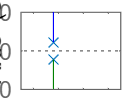

rlocus(G);

The closed loop system will be stable for any C(s)=K. However, the system will have non-zero steady state error to step inputs, i.e.,


$$\frac{1}{1+L(0)} = \frac{1}{1+K/40}$$


The larger K, the smaller the steady state error. To see this, let's compare

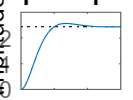

K = 1;
step(minreal(K*G/(1+K*G)));

and 

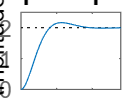

K = 10;
step(minreal(K*G/(1+K*G)));

In order to have zero steady state error, we will need to add an integrator term. Let's try with a PI controller.

The PI controller is given by


$$C(s)= k_p+\frac{k_i}{s} = k_p \frac{s+a}{s}$$


with


$$a = k_i/k_p$$


For example, let

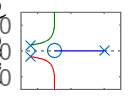

kp = 1; ki = 3;
C = kp + ki/s;
rlocus(C*G);

With a gain of 32 we should be able to bring the slowest pole at around -1

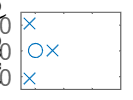

K = 100;
C = K*C;
pzplot(minreal(C*G/(1+C*G)));

Let's verify that the steady state error to step inputs is zero

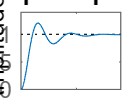

step(minreal(C*G/(1+C*G)));

[numC denC] = tfdata(C, 'v');